%% ═══════════════════════════════════════════════════════════════════════════
%% DROWSINESS DETECTION PIPELINE
%% Stage 1 : MediaPipe face detector  (face_detector_merged.onnx)
%% Stage 2 : MediaPipe face landmarks (face_landmark_detector_merged.onnx)
%% Stage 3 : Drowsiness classifier    (drowsiness_matlab.onnx)
%% ═══════════════════════════════════════════════════════════════════════════

%% ── STAGE 0 : Load all three networks ───────────────────────────────────────
detectorNet   = importNetworkFromONNX("face_detector_merged.onnx");
landmarkNet   = importNetworkFromONNX("face_landmark_detector_merged.onnx");
drowsinessNet = importNetworkFromONNX("drowsiness_matlab.onnx");


%% ── STAGE 1 : Load image & preprocess for face detector (256×256) ───────────
img_orig = imread("attempt1.png");
[origH, origW, ~] = size(img_orig);

img256 = imresize(img_orig, [256 256]);
img256 = im2single(img256) * 2 - 1;     % [-1, 1] MediaPipe normalisation

detInput = dlarray(img256, "SSCB");

%% ── STAGE 2 : Run face detector ─────────────────────────────────────────────
[box_coords_1, box_coords_2, box_scores_1, box_scores_2] = predict(detectorNet, detInput);

% sigmoid on dlarray BEFORE extractdata
scores1 = extractdata(sigmoid(box_scores_1));   % [1, 512, 1]
scores2 = extractdata(sigmoid(box_scores_2));   % [1, 384, 1]
coords1 = extractdata(box_coords_1);            % [1, 512, 16]
coords2 = extractdata(box_coords_2);            % [1, 384, 16]

% Flatten — use (:)' to guarantee row vectors regardless of squeeze shape
all_scores = [scores1(:)', scores2(:)'];        % [1, 896]

c1 = reshape(coords1, 512, 16);
c2 = reshape(coords2, 384, 16);
all_coords = [c1(:,1:4); c2(:,1:4)];           % [896, 4]  cx cy w h

% Best detection
CONF_THRESH = 0.5;
[best_score, best_idx] = max(all_scores);

if best_score < CONF_THRESH
    error("No face detected (best confidence = %.2f)", best_score);
end
fprintf("Face detected  —  confidence: %.2f\n", best_score);

Face detected  —  confidence: 0.61



%% ── STAGE 3 : Decode bounding box & crop face ───────────────────────────────
cx = all_coords(best_idx, 1) / 256;
cy = all_coords(best_idx, 2) / 256;
bw = all_coords(best_idx, 3) / 256;
bh = all_coords(best_idx, 4) / 256;

PAD = 0.25;
x1 = max(0, cx - bw/2 - PAD*bw);
y1 = max(0, cy - bh/2 - PAD*bh);
x2 = min(1, cx + bw/2 + PAD*bw);
y2 = min(1, cy + bh/2 + PAD*bh);

px1 = max(1,     round(x1 * origW));
py1 = max(1,     round(y1 * origH));
px2 = min(origW, round(x2 * origW));
py2 = min(origH, round(y2 * origH));

face_crop = img_orig(py1:py2, px1:px2, :);

%% ── STAGE 4 : Run landmark detector (192×192) ────────────────────────────────
face192 = imresize(face_crop, [192 192]);
face192 = im2single(face192) * 2 - 1;

lmInput = dlarray(face192, "SSCB");
[lm_scores, lm_landmarks] = predict(landmarkNet, lmInput);

face_present = extractdata(sigmoid(lm_scores));
landmarks    = squeeze(extractdata(lm_landmarks));  % [468, 3]

fprintf("Face presence score: %.2f\n", face_present);

Face presence score: 0.50



% Map X/Y from crop space [0,192] back to original image pixels
lm_x = landmarks(:,1) / 192 * (px2 - px1) + px1;
lm_y = landmarks(:,2) / 192 * (py2 - py1) + py1;

%% ── STAGE 5 : Run drowsiness classifier on cropped face (224×224) ───────────
face_cls = imresize(face_crop, [224 224]);
face_cls = im2single(face_cls);

mean_val = reshape([0.485, 0.456, 0.406], 1, 1, 3);
std_val  = reshape([0.229, 0.224, 0.225], 1, 1, 3);
face_cls = (face_cls - mean_val) ./ std_val;

clsInput = dlarray(face_cls, "SSCB");
logits   = predict(drowsinessNet, clsInput);

scores_cls = extractdata(logits(:));
[~, classIdx] = max(scores_cls);

probs  = exp(scores_cls) / sum(exp(scores_cls));
labels = ["Drowsy", "Non Drowsy"];

fprintf("\n── Classifier result ──────────────────────────\n");


── Classifier result ──────────────────────────


fprintf("Prediction : %s\n",    labels(classIdx));

Prediction : Non Drowsy


fprintf("Drowsy     : %.1f%%\n", probs(1)*100);

Drowsy     : 1.0%


fprintf("Non Drowsy : %.1f%%\n", probs(2)*100);

Non Drowsy : 99.0%



%% ── STAGE 6 : EAR from landmarks ────────────────────────────────────────────
% MediaPipe indices are 0-based → +1 for MATLAB
LEFT_EYE  = [33, 160, 158, 133, 153, 144] + 1;
RIGHT_EYE = [362, 385, 387, 263, 373, 380] + 1;
MOUTH     = [61, 291, 13, 14, 17, 0]      + 1;

left_EAR  = eyeAspectRatio(landmarks, LEFT_EYE);
right_EAR = eyeAspectRatio(landmarks, RIGHT_EYE);
avg_EAR   = (left_EAR + right_EAR) / 2;

fprintf("\n── Landmark EAR ────────────────────────────────\n");


── Landmark EAR ────────────────────────────────


fprintf("Left  EAR : %.3f\n", left_EAR);

Left  EAR : 0.225


fprintf("Right EAR : %.3f\n", right_EAR);

Right EAR : 0.210


fprintf("Avg   EAR : %.3f  (threshold ~0.21)\n", avg_EAR);

Avg   EAR : 0.218  (threshold ~0.21)



%% ── STAGE 7 : Combined decision ─────────────────────────────────────────────
ear_drowsy = avg_EAR < 0.21;
cls_drowsy = classIdx == 1;

fprintf("\n── Combined Decision ───────────────────────────\n");


── Combined Decision ───────────────────────────


if ear_drowsy && cls_drowsy
    fprintf("DROWSY  (both EAR and classifier agree)\n");
elseif ear_drowsy || cls_drowsy
    fprintf("WARNING (one signal — EAR=%d  CLS=%d)\n", ear_drowsy, cls_drowsy);
else
    fprintf("ALERT\n");
end

ALERT


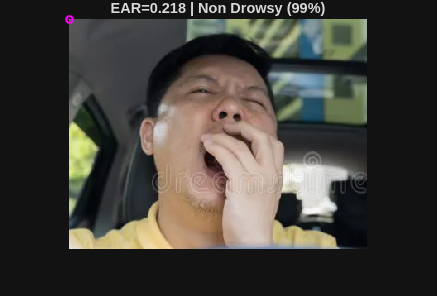


%% ── STAGE 8 : Visualise landmarks ───────────────────────────────────────────
figure;
imshow(img_orig); hold on;

% All 468 landmarks — small grey dots
plot(lm_x, lm_y, '.', 'Color', [0.6 0.6 0.6], 'MarkerSize', 2);

% Left eye — cyan
plot(lm_x(LEFT_EYE),  lm_y(LEFT_EYE), 'o', 'Color', 'c', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([LEFT_EYE,  LEFT_EYE(1)]),  lm_y([LEFT_EYE,  LEFT_EYE(1)]),  'c-', 'LineWidth', 1.2);

% Right eye — yellow
plot(lm_x(RIGHT_EYE), lm_y(RIGHT_EYE), 'o', 'Color', 'y', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([RIGHT_EYE, RIGHT_EYE(1)]), lm_y([RIGHT_EYE, RIGHT_EYE(1)]), 'y-', 'LineWidth', 1.2);

% Mouth — magenta
plot(lm_x(MOUTH),     lm_y(MOUTH),    'o', 'Color', 'm', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([MOUTH,     MOUTH(1)]),     lm_y([MOUTH,     MOUTH(1)]),     'm-', 'LineWidth', 1.2);

title(sprintf('EAR=%.3f | %s (%.0f%%)', avg_EAR, labels(classIdx), probs(classIdx)*100));
hold off;


%% ── Helper function ──────────────────────────────────────────────────────────
function ear = eyeAspectRatio(lm, indices)
    pts = lm(indices, 1:2);
    A   = norm(pts(2,:) - pts(6,:));
    B   = norm(pts(3,:) - pts(5,:));
    C   = norm(pts(1,:) - pts(4,:));
    ear = (A + B) / (2.0 * C);
end